clear; clc; close all;

%% 1. 参数设置
stepFile = 'D:\QEAsHomework\ship.step'; % 文件路径
% [重要] 如果STEP单位是mm，这里填 0.001；如果是m，填 1.0
% 提示：如果网格生成仍然困难，尝试先在此处不缩放(设为1.0)，在生成网格后再统一缩放nodes
scale_factor = 1.0; 
rho_ship = 0.5;     % 船体密度 (t/m^3)
rho_water = 1.025;  % 海水密度 (t/m^3)
g = 9.81;

%% 2. 导入与预处理 (修正坐标系)
fprintf('========== 1. 模型初始化 ==========\n');

========== 1. 模型初始化 ==========


model = createpde();
try
    importGeometry(model, stepFile);
catch
    error('无法导入文件，请检查路径。');
end

% [修改点]：优化网格生成参数以解决 associativity 错误
% 1. 减小 Hmax 以捕捉细节
% 2. 增加 Hmin 防止在极小特征处过度加密导致错误
% 3. 将 GeometricOrder 设为 'quadratic' 可能会提高几何贴合度，但 'linear' 计算更快且通常足够稳性计算
fprintf('正在生成网格 (可能需要几秒钟)... \n');

正在生成网格 (可能需要几秒钟)... 


try
    % 尝试更加精细的网格参数
    % 如果模型尺寸较大(如几十米)，Hmax=0.5可能太粗糙
    % 如果模型是mm单位(如几千mm)，Hmax=0.5可能太小
    % 这里假设模型单位是米，尝试减小 Hmax 并设置 Hmin
    generateMesh(model, 'Hmax', 0.004, 'Hmin', 0.00016, 'GeometricOrder', 'linear');
catch ME
    fprintf('尝试使用更保守的网格参数重试...\n');
    % 备用方案：允许更宽的尺寸范围
    generateMesh(model, 'Hmax', 0.5, 'Hmin', 0.01, 'GeometricOrder', 'linear');
end

nodes = model.Mesh.Nodes * scale_factor; % 应用单位缩放
elements = model.Mesh.Elements;

% [核心修正]：将模型移至几何中心 (0,0,0)
% 之前是 Z 对齐到底部，导致旋转时像钟摆。现在改为 Z 对齐到几何中心。
x_mean = mean(nodes(1,:));
y_mean = mean(nodes(2,:));
z_mid  = (min(nodes(3,:)) + max(nodes(3,:))) / 2; % 找出 Z 方向的中点

nodes(1,:) = nodes(1,:) - x_mean; % X居中
nodes(2,:) = nodes(2,:) - y_mean; % Y居中
nodes(3,:) = nodes(3,:) - z_mid;  % Z居中 (现在旋转轴在船身中间了！)

fprintf('模型已归一化：中心对齐原点，船底对齐 Z=0\n');

模型已归一化：中心对齐原点，船底对齐 Z=0


fprintf('模型尺寸 (m): 长=%.3f, 宽=%.3f, 高=%.3f\n', ...
    range(nodes(1,:)), range(nodes(2,:)), range(nodes(3,:)));

模型尺寸 (m): 长=0.650, 宽=0.300, 高=0.165



% [新增] 提取表面网格用于三维显示
% 这一步非常关键，它从四面体体网格中提取出外表面三角形，用于 trisurf 绘图
fprintf('正在提取表面网格用于三维显示...\n');

正在提取表面网格用于三维显示...


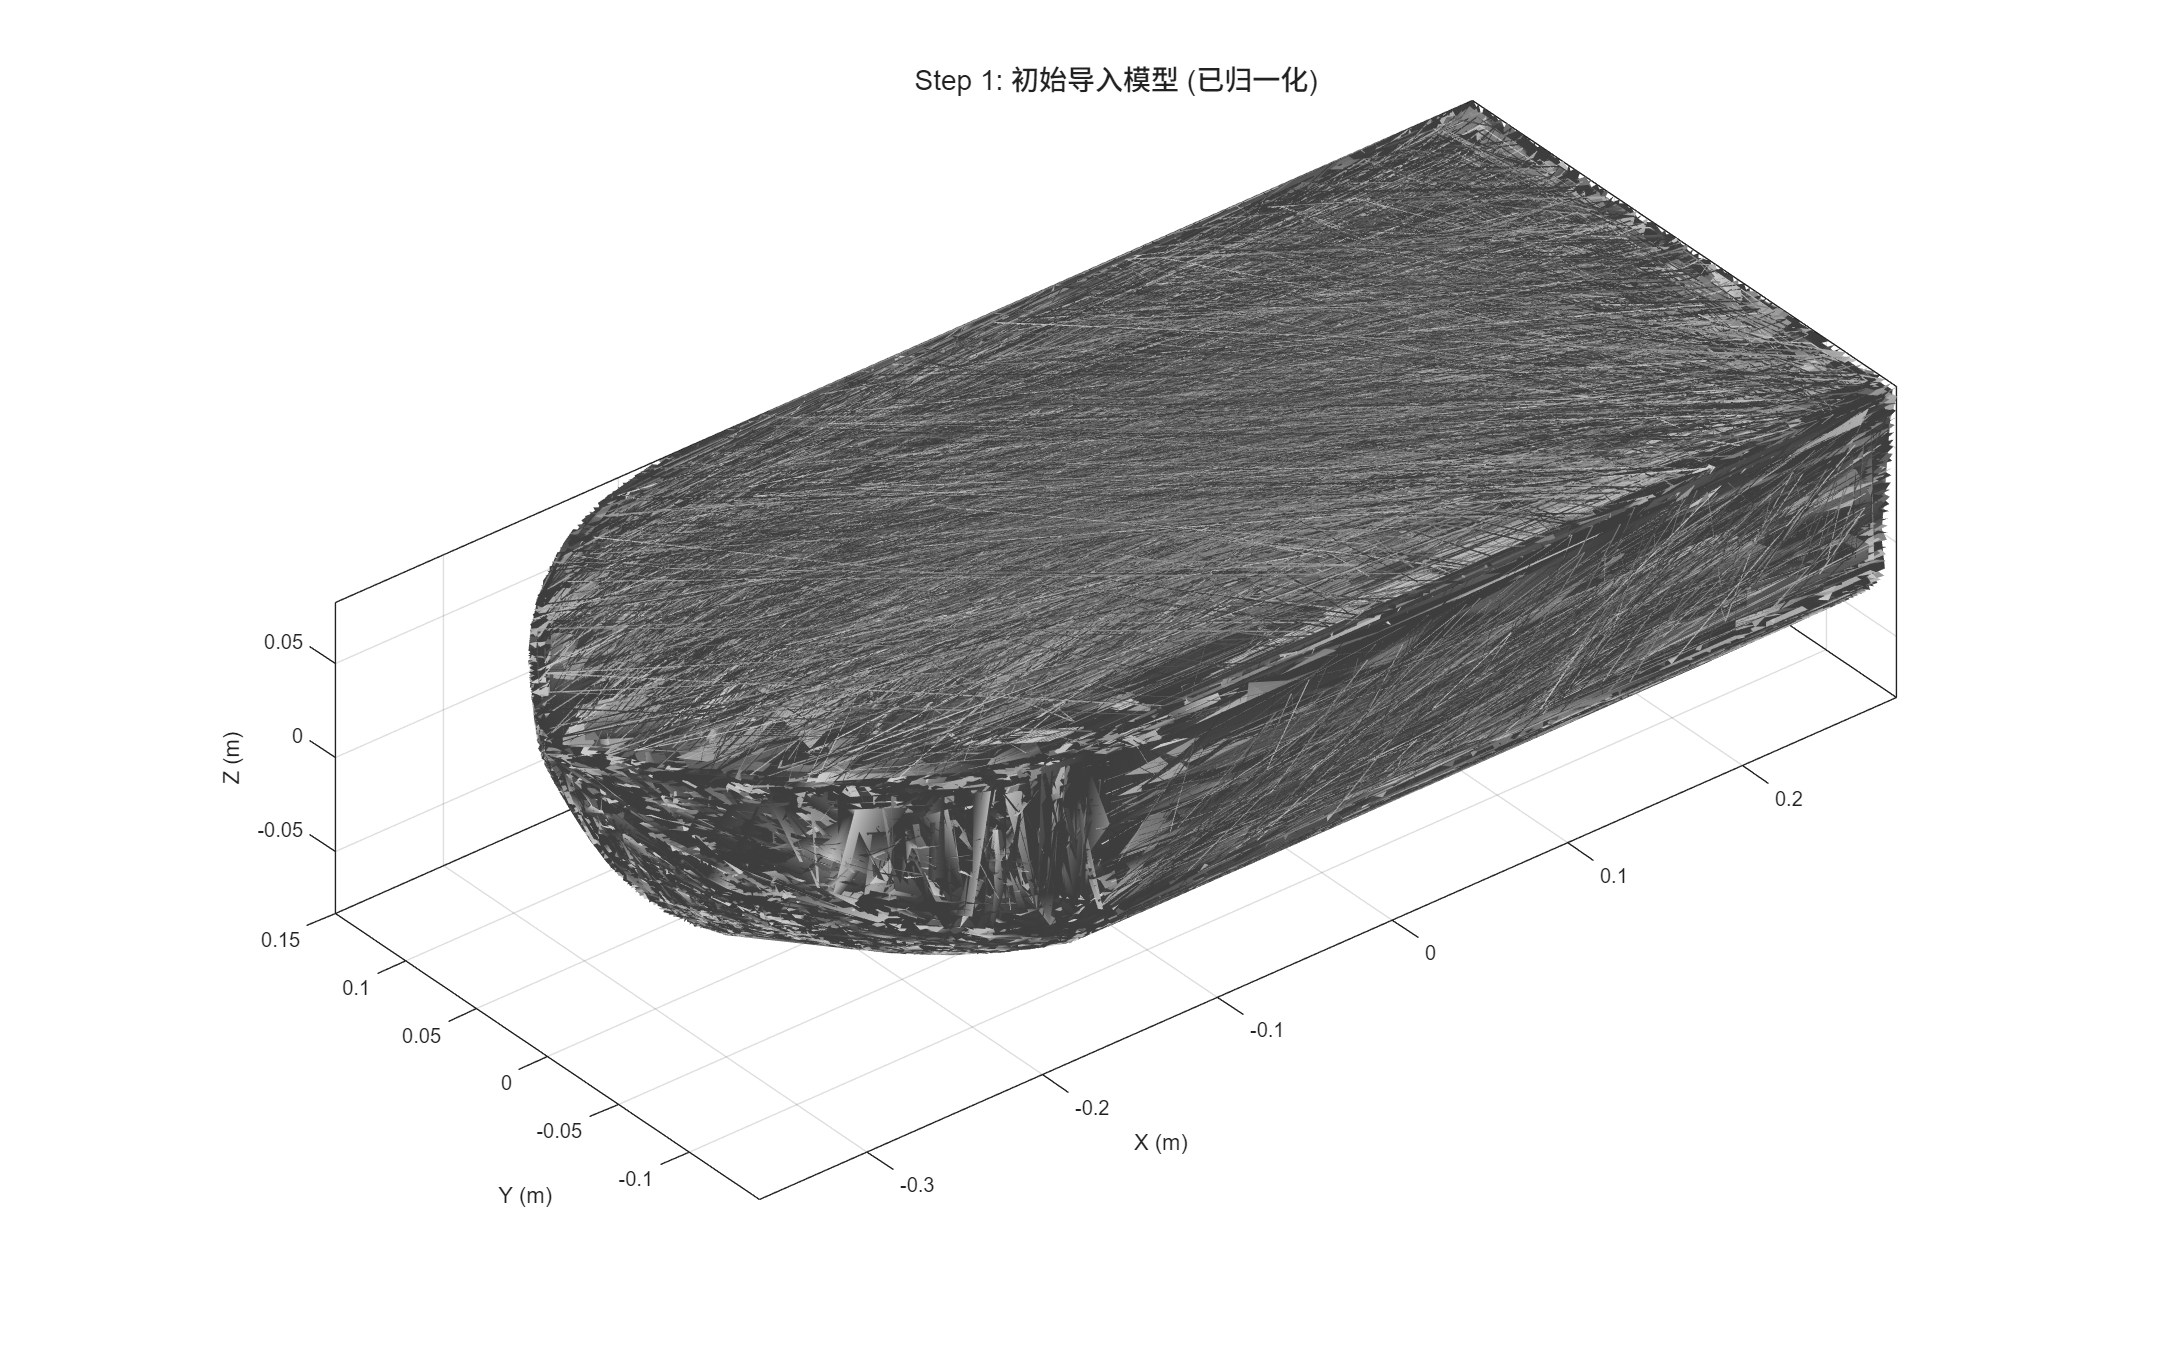

TR = triangulation(elements(1:4,:)', nodes');
[F_surface, ~] = freeBoundary(TR); % 获取表面三角形索引

%% 2.1 第一步：展示导入的模型 (三维视图)
figure('Name', 'Step 1: 初始模型预览', 'Color', 'w', 'Units', 'normalized', 'OuterPosition', [0 0 1 1]);
trisurf(F_surface, nodes(1,:), nodes(2,:), nodes(3,:), ...
    'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 1.0);
light('Position', [10 10 10], 'Style', 'infinite'); % 添加光照
lighting gouraud; % 平滑着色
material dull;
axis equal; grid on; box on;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Step 1: 初始导入模型 (已归一化)', 'FontSize', 14);
view(3); % 标准三维视角

drawnow;

%% 3. 计算物理属性
[vol_total, cg_local] = calc_mesh_props(nodes, elements);
mass = vol_total * rho_ship;
target_disp = mass / rho_water;

fprintf('船体质量: %.2f t\n', mass);

船体质量: 0.00 t


fprintf('重心位置 (KG): [%.2f, %.2f, %.2f]\n', cg_local);

重心位置 (KG): [0.01, 0.00, 0.01]


fprintf('目标排水体积: %.2f m^3\n', target_disp);

目标排水体积: 0.00 m^3



%% 4. 初始平衡吃水
draft_init = find_draft(nodes, elements, target_disp, 0, max(nodes(3,:)));
fprintf('初始平衡吃水: %.3f m\n', draft_init);

初始平衡吃水: 0.016 m



% 更新重心的绝对高度 (假设重心固定在船体上)
% 此时重心坐标 cg_local 是相对于船体几何的，随船体旋转而旋转

%% 5. 循环计算 (平滑积分逻辑)
angles = 0:5:90; % 可视化选取的角度 (已扩展到90度)
results_angle = [];
results_gz = [];

% 准备绘图画布
% figure('Name', '船体倾斜姿态可视化', 'Color', 'w', 'Position', [100, 100, 1400, 900]);
% tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');

fprintf('\n========== 2. 开始计算与绘图 ==========\n');


========== 2. 开始计算与绘图 ==========


计算倾角: 0° ... 

GZ = 0.000 m


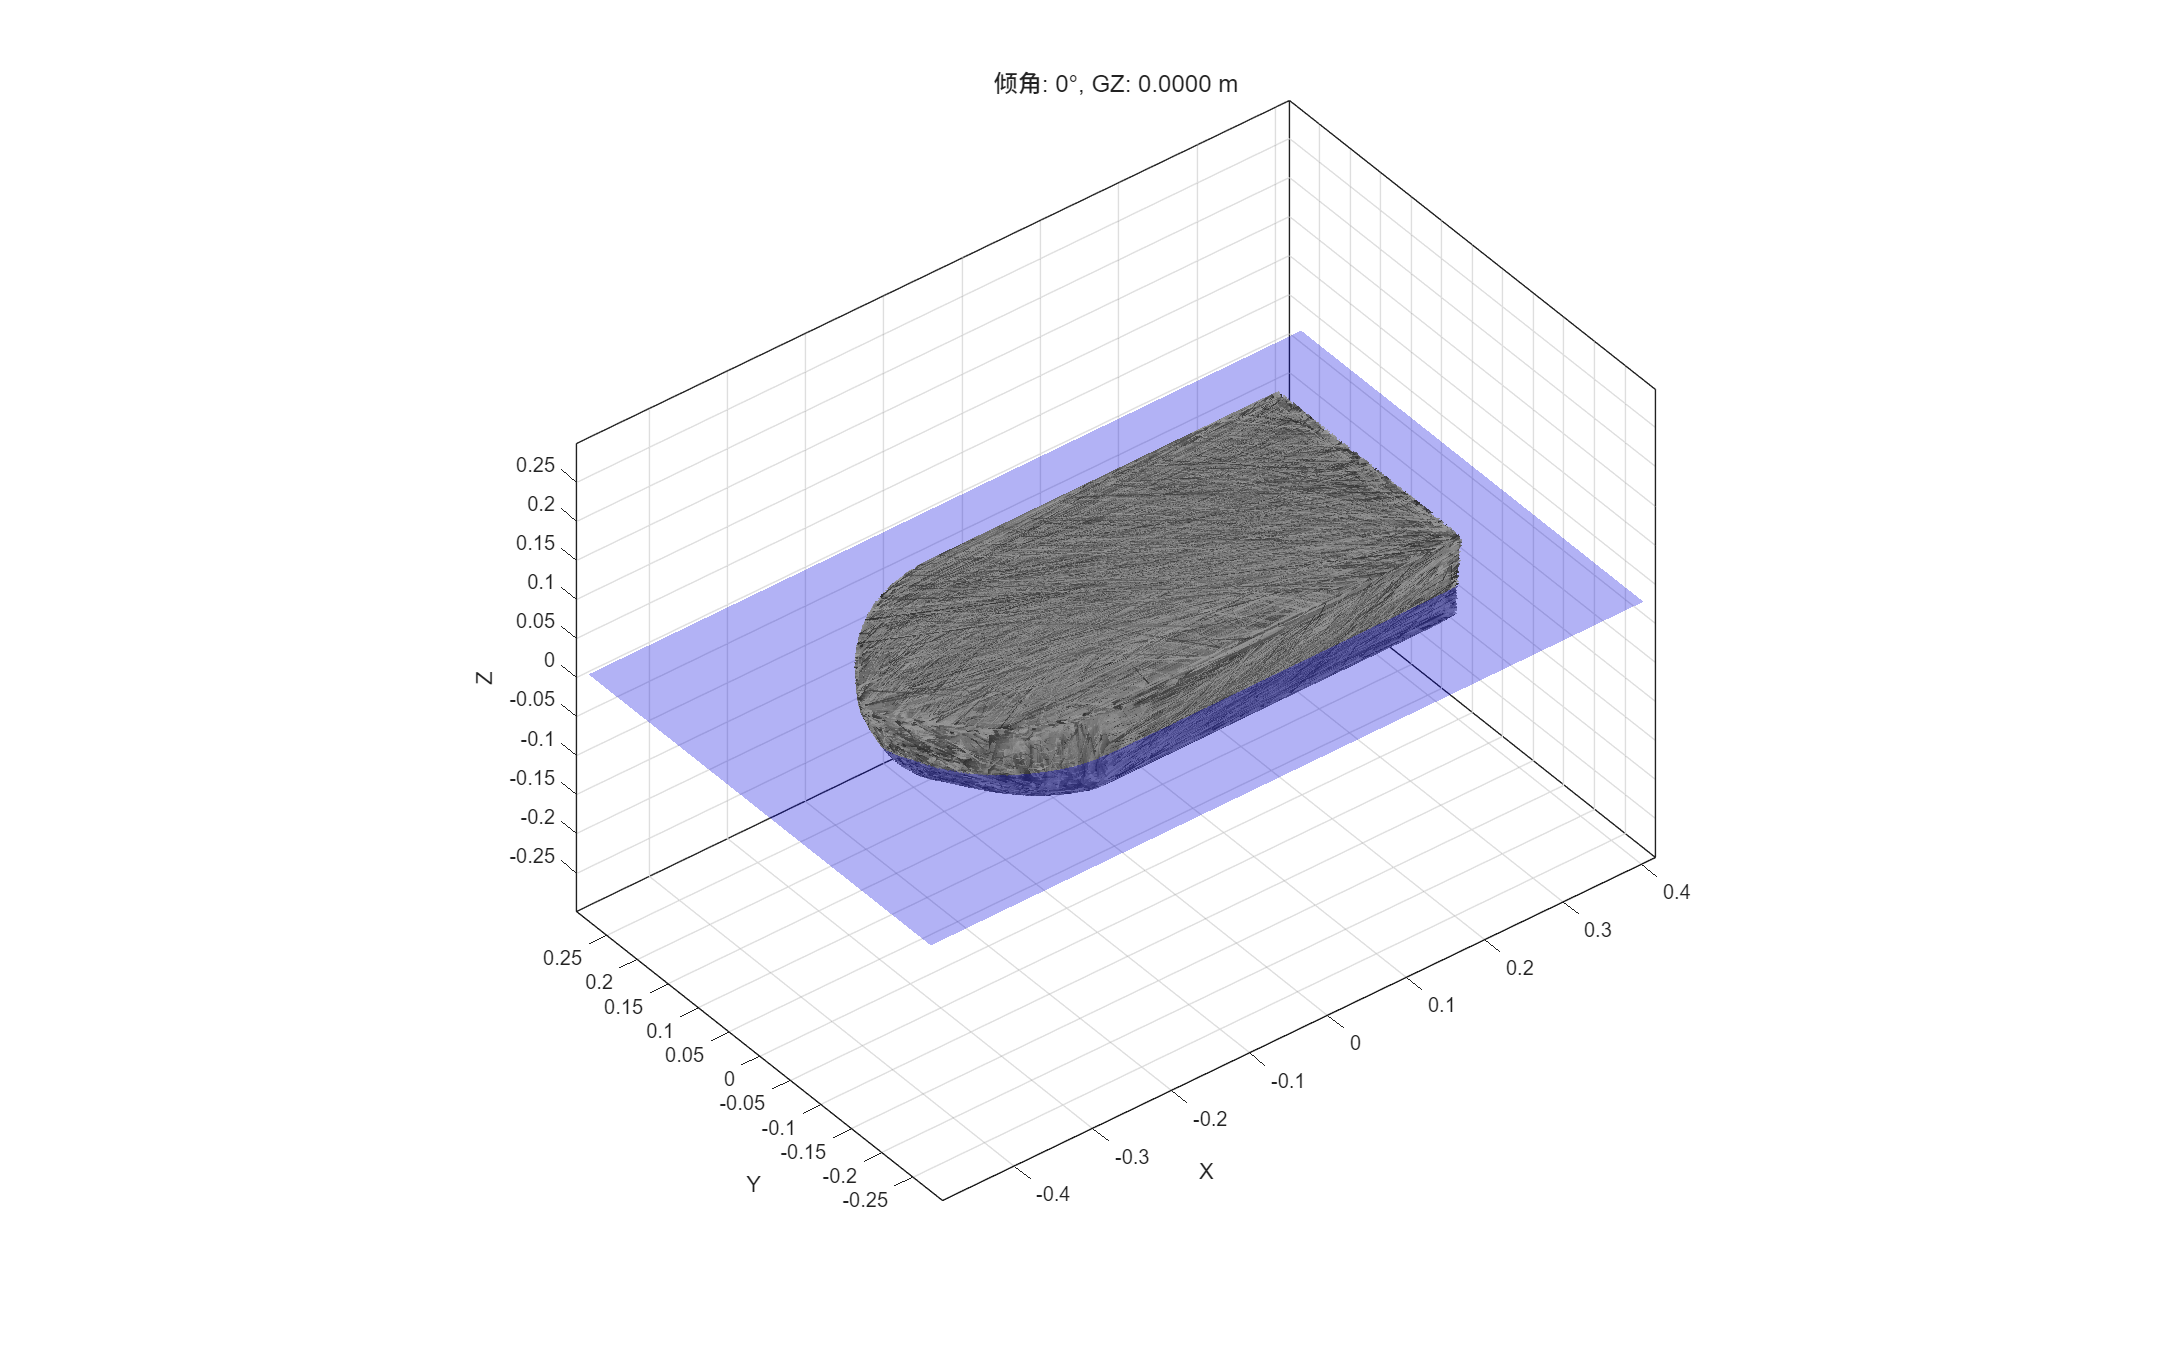

计算倾角: 5° ... 

GZ = 0.004 m


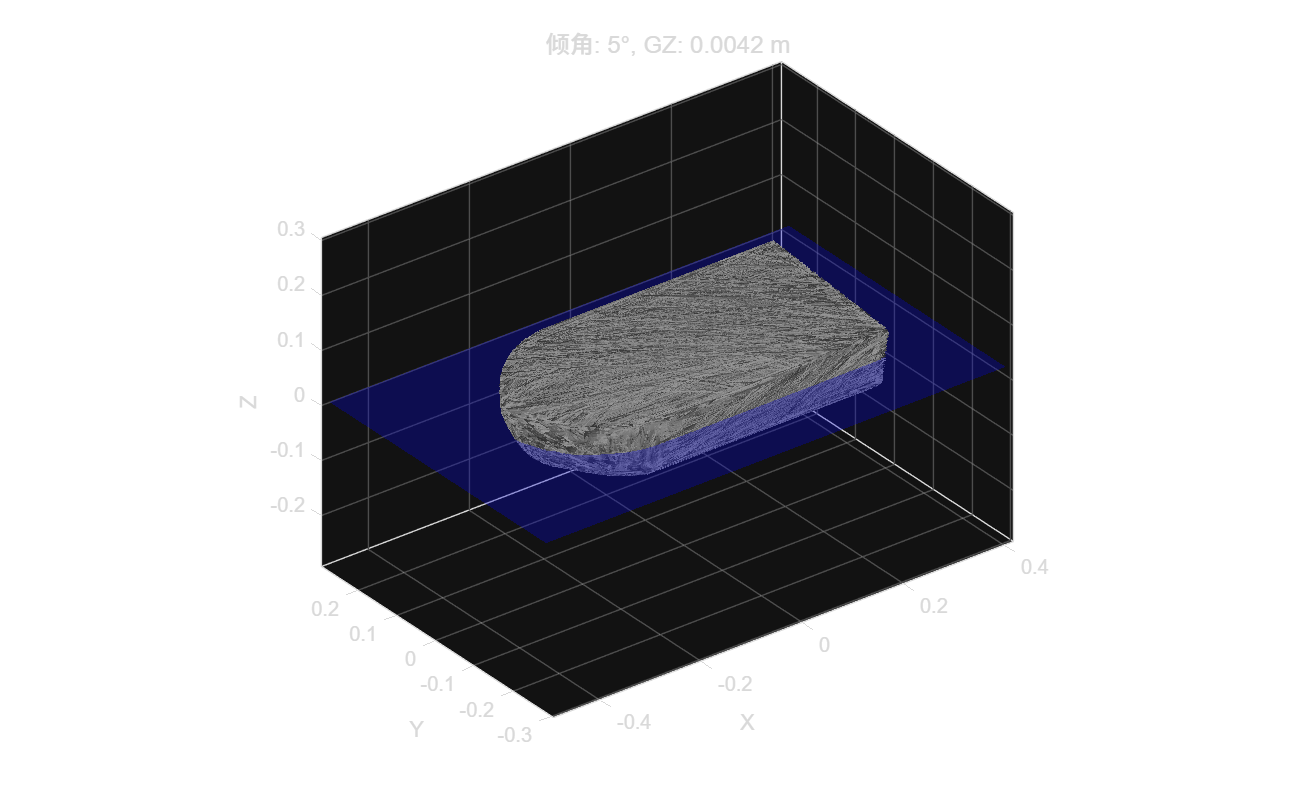

计算倾角: 10° ... 

GZ = 0.009 m


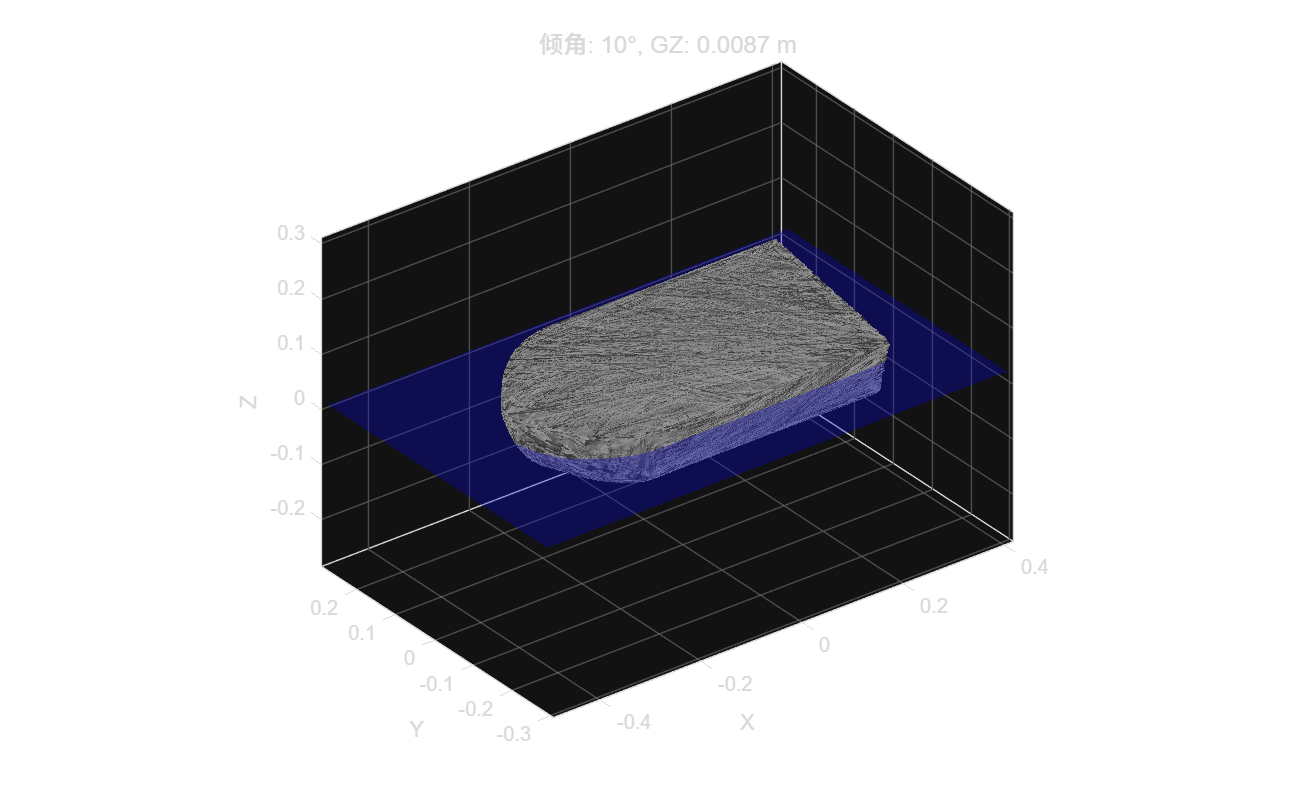

计算倾角: 15° ... 

GZ = 0.013 m


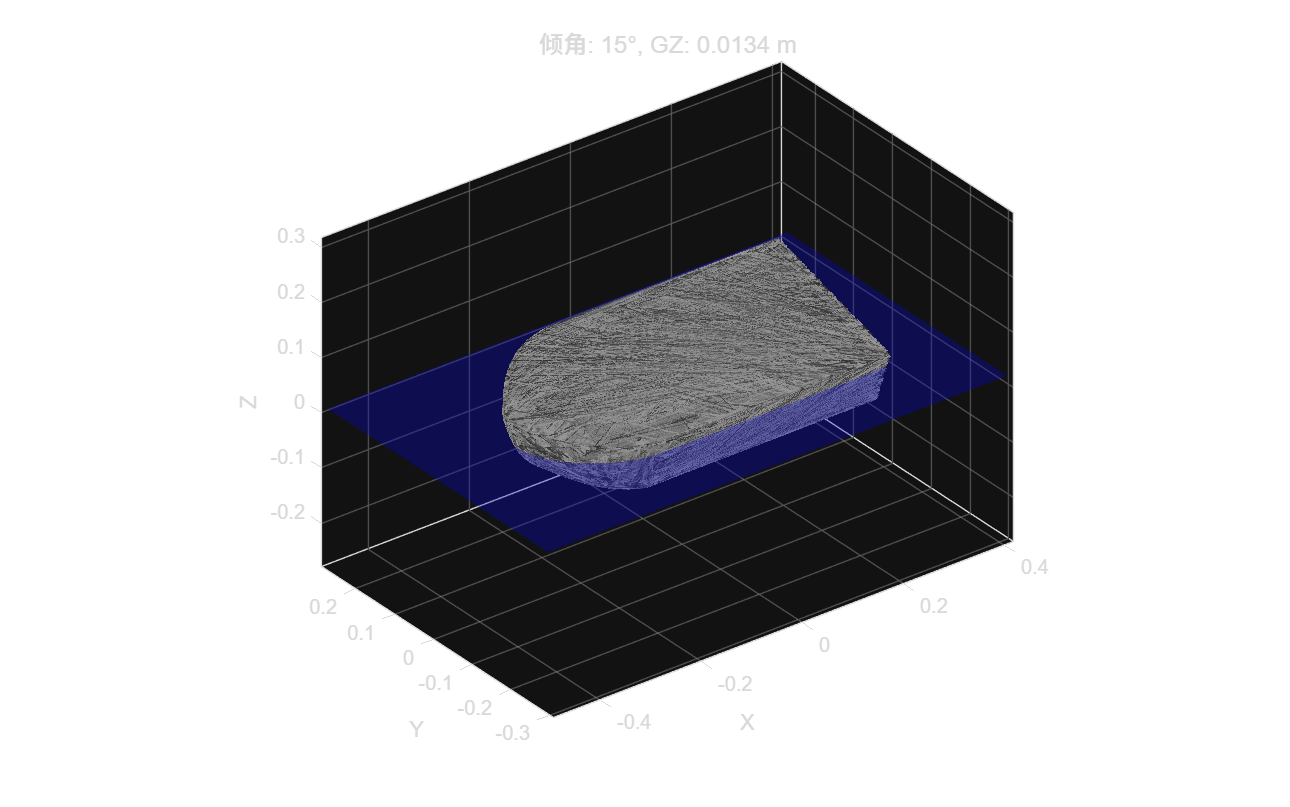

计算倾角: 20° ... 

GZ = 0.019 m


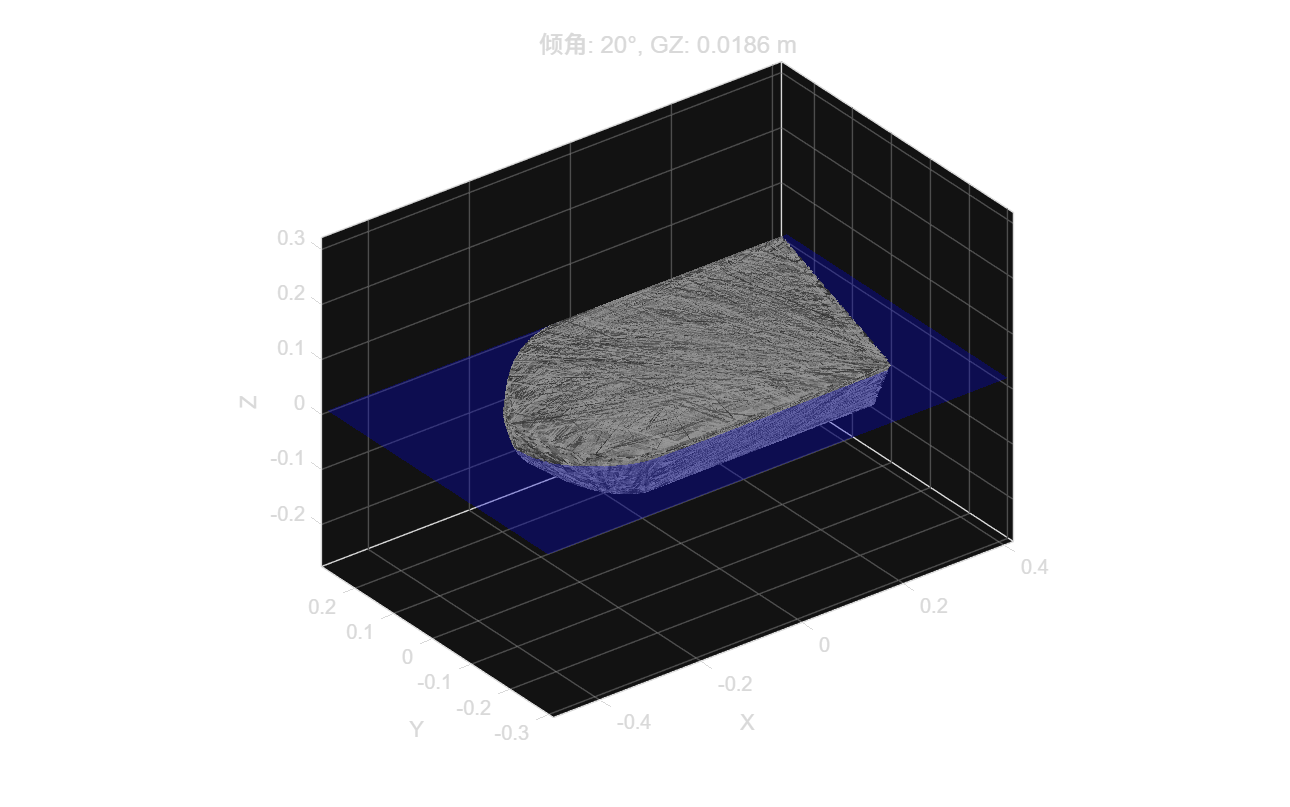

计算倾角: 25° ... 

GZ = 0.024 m


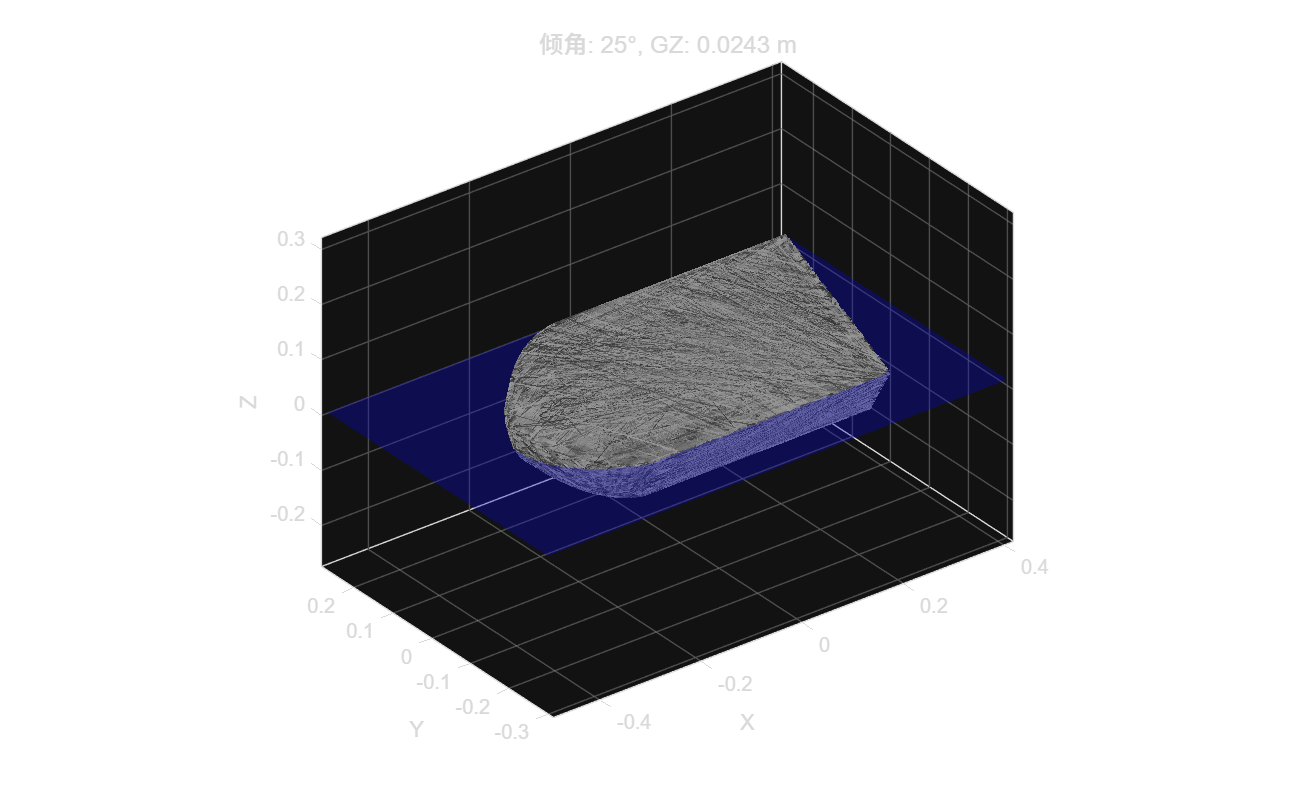

计算倾角: 30° ... 

GZ = 0.031 m


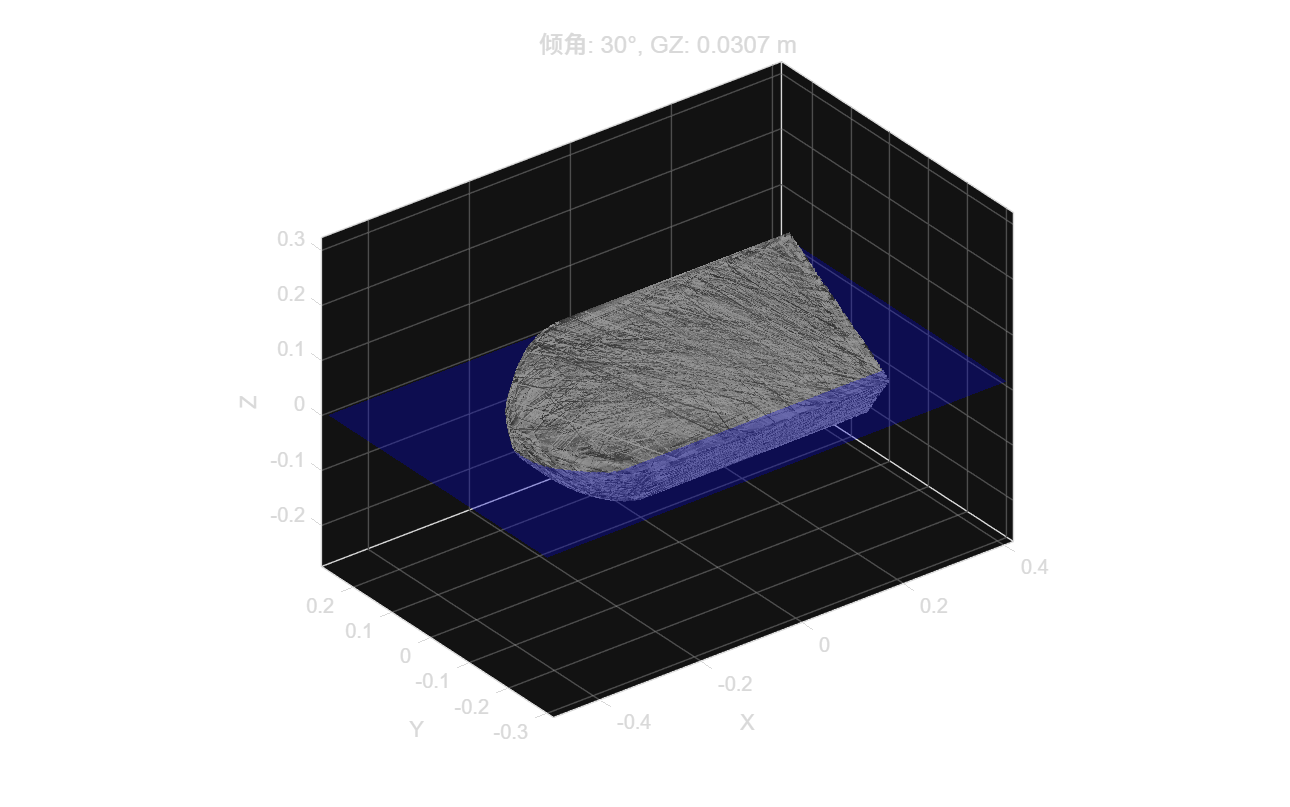

计算倾角: 35° ... 

GZ = 0.034 m


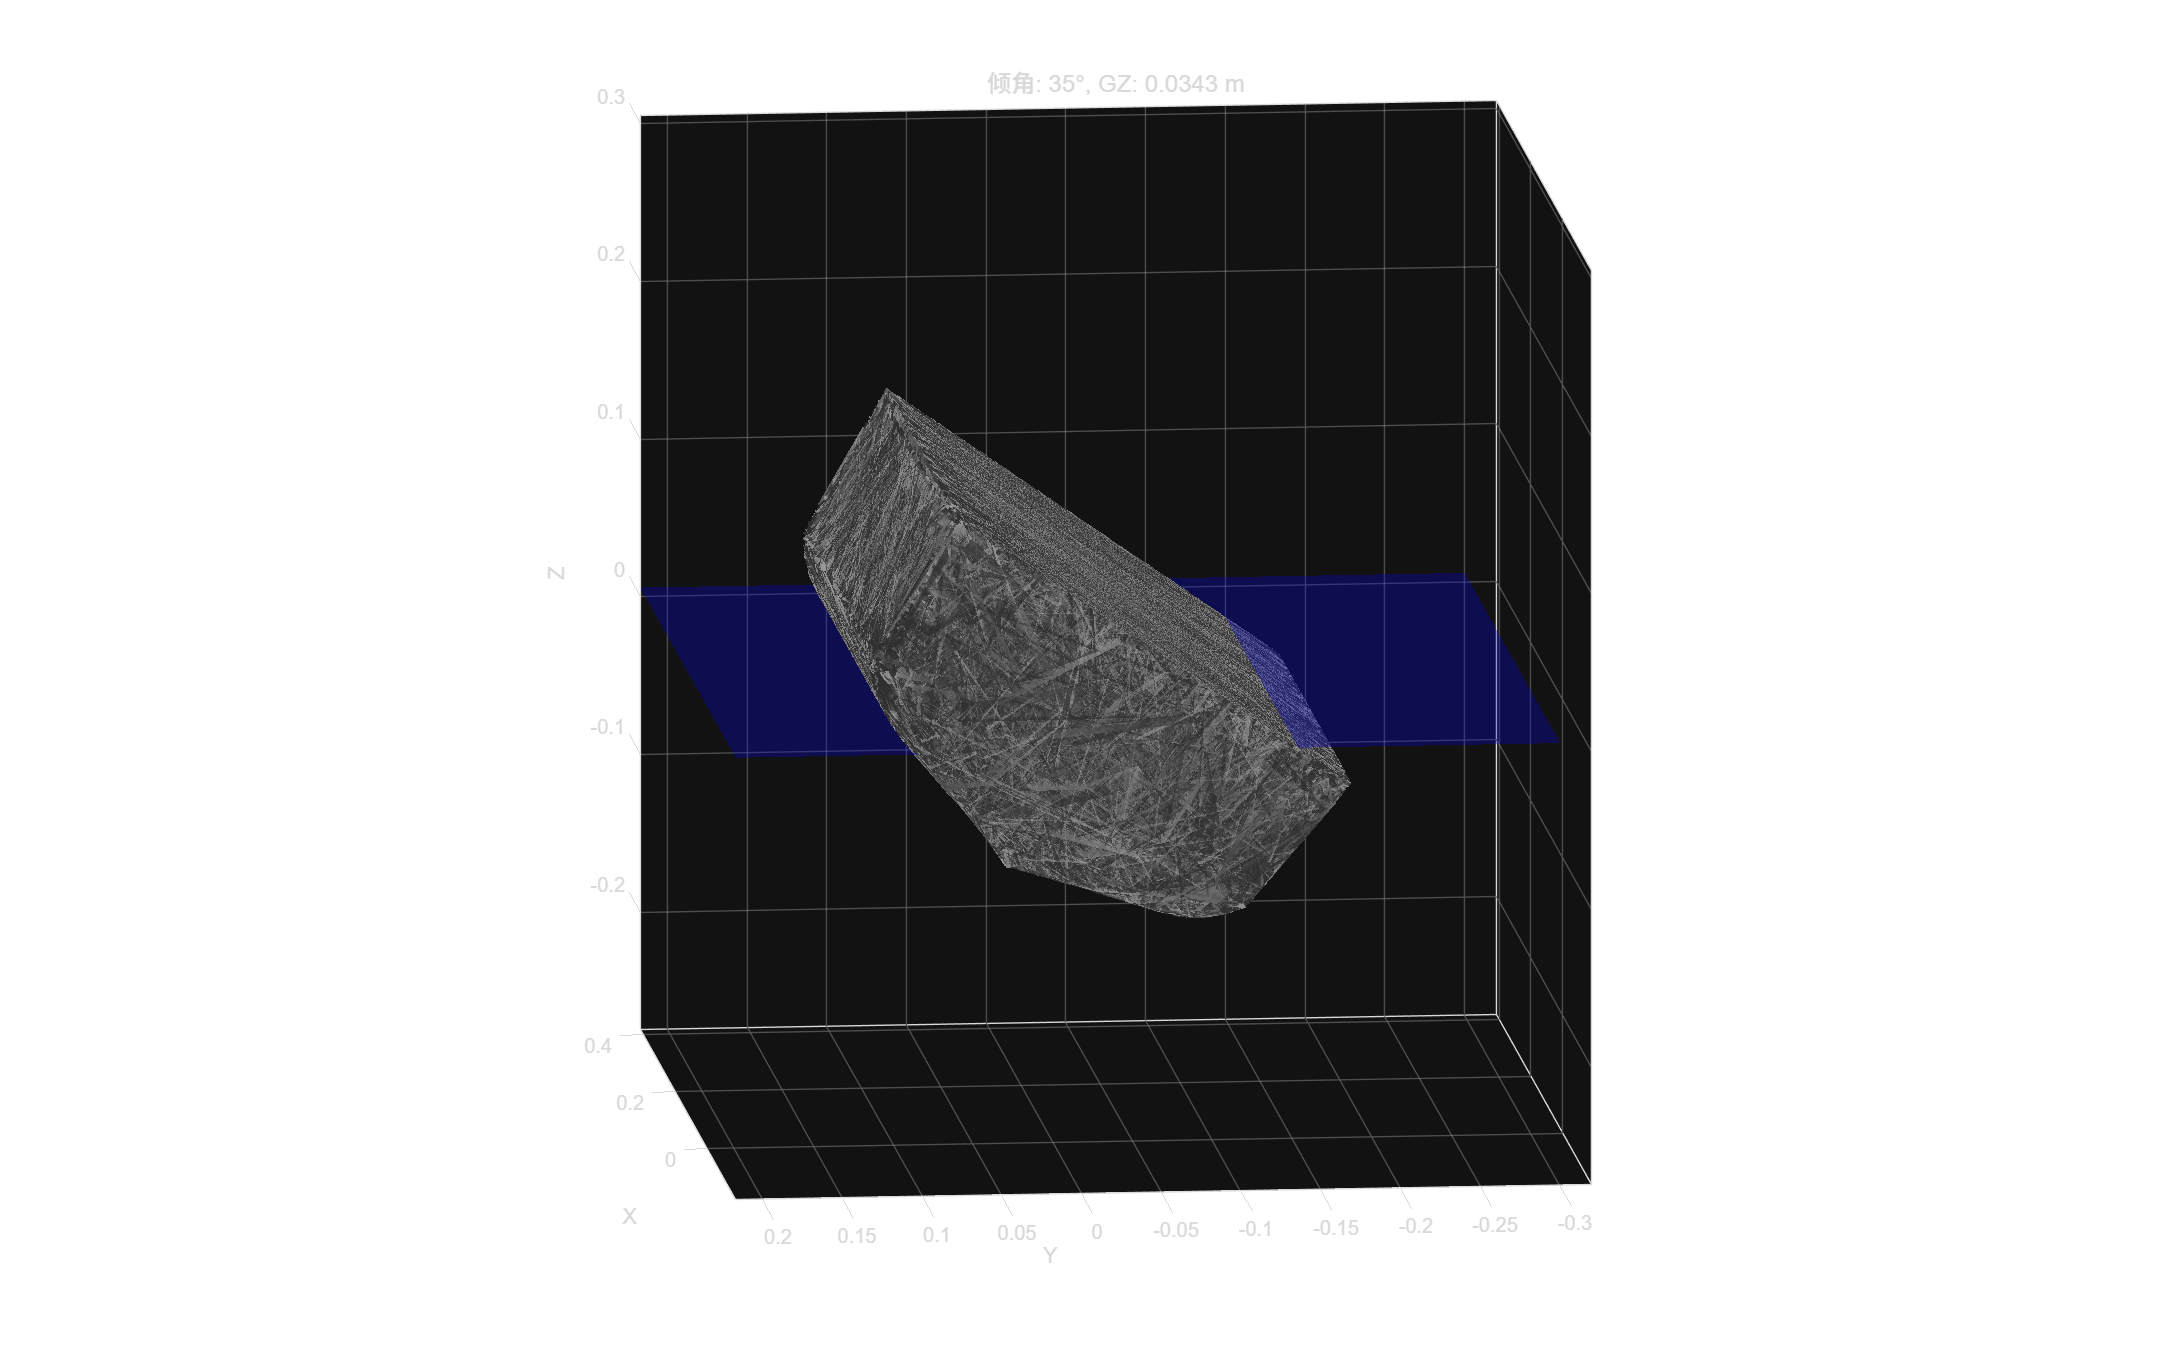

计算倾角: 40° ... 

GZ = 0.036 m


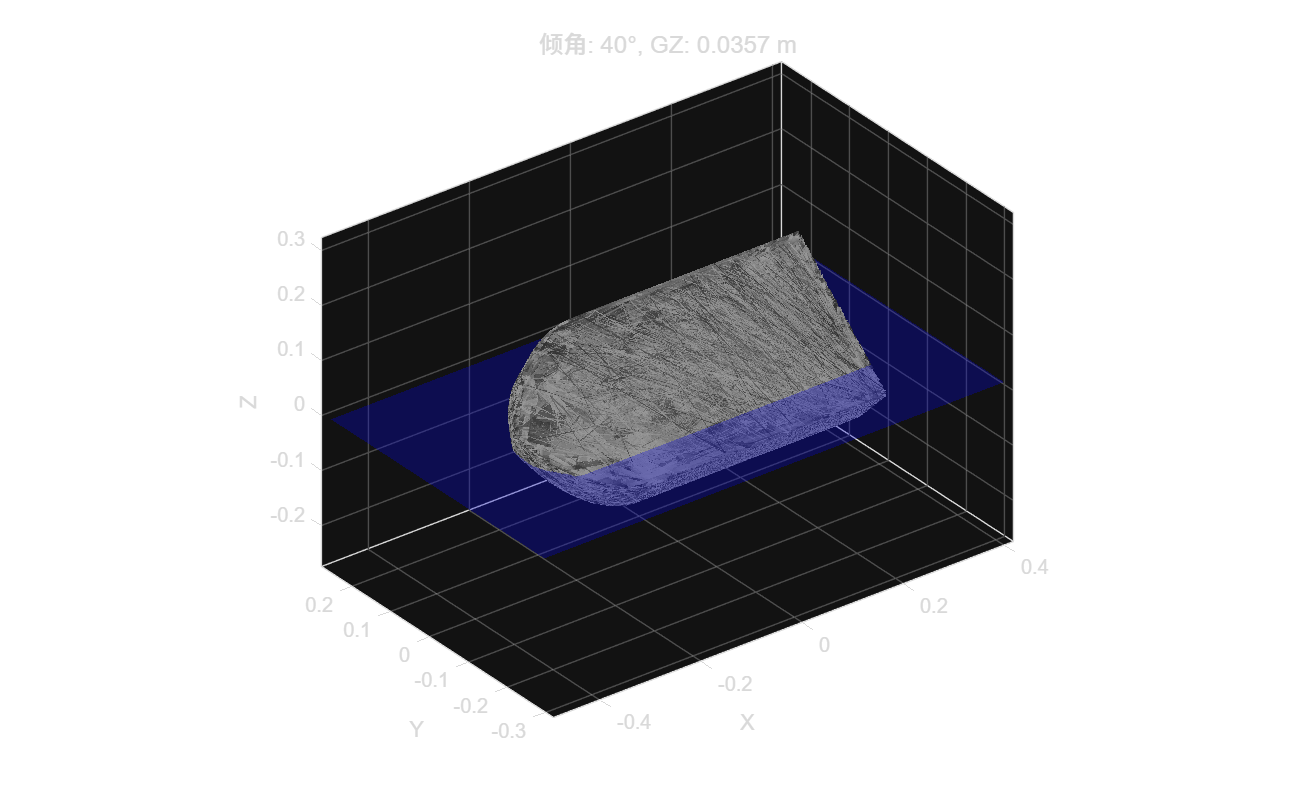

计算倾角: 45° ... 

GZ = 0.035 m


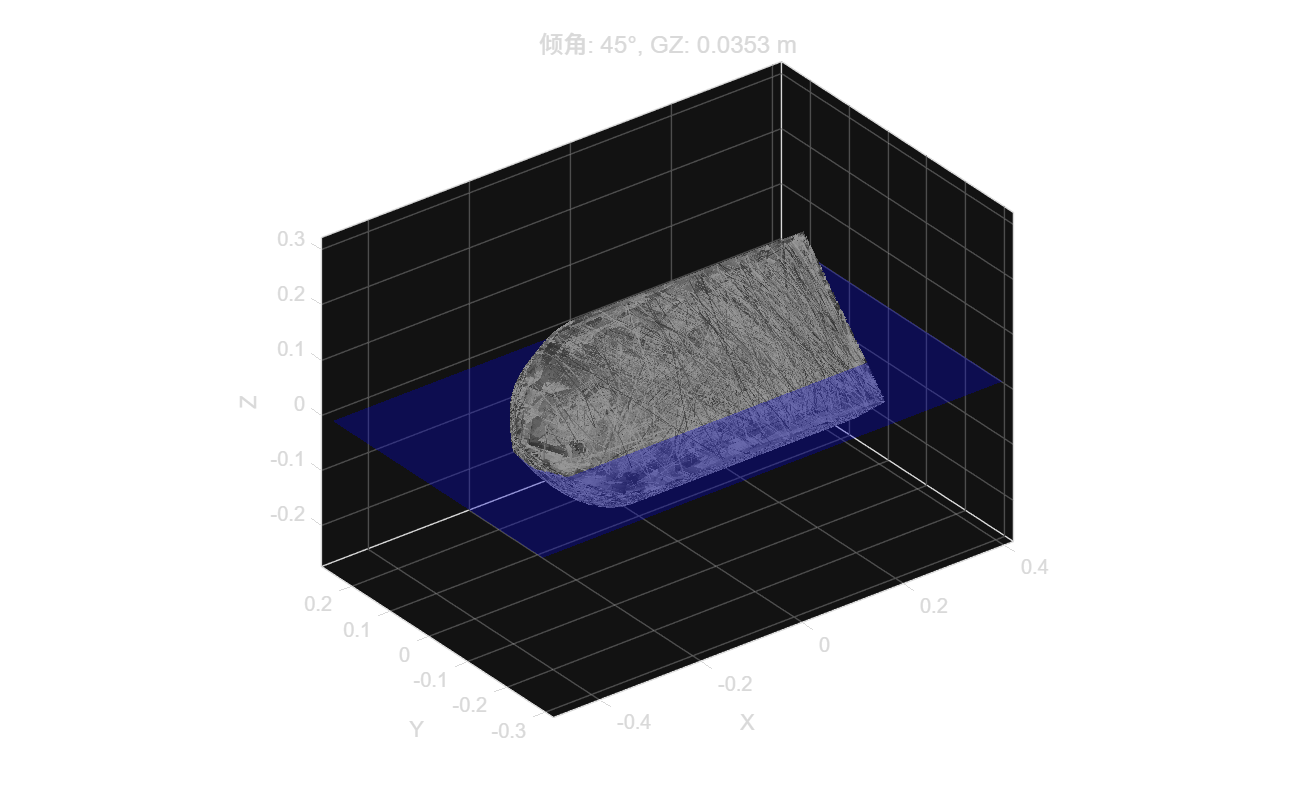

计算倾角: 50° ... 

GZ = 0.034 m


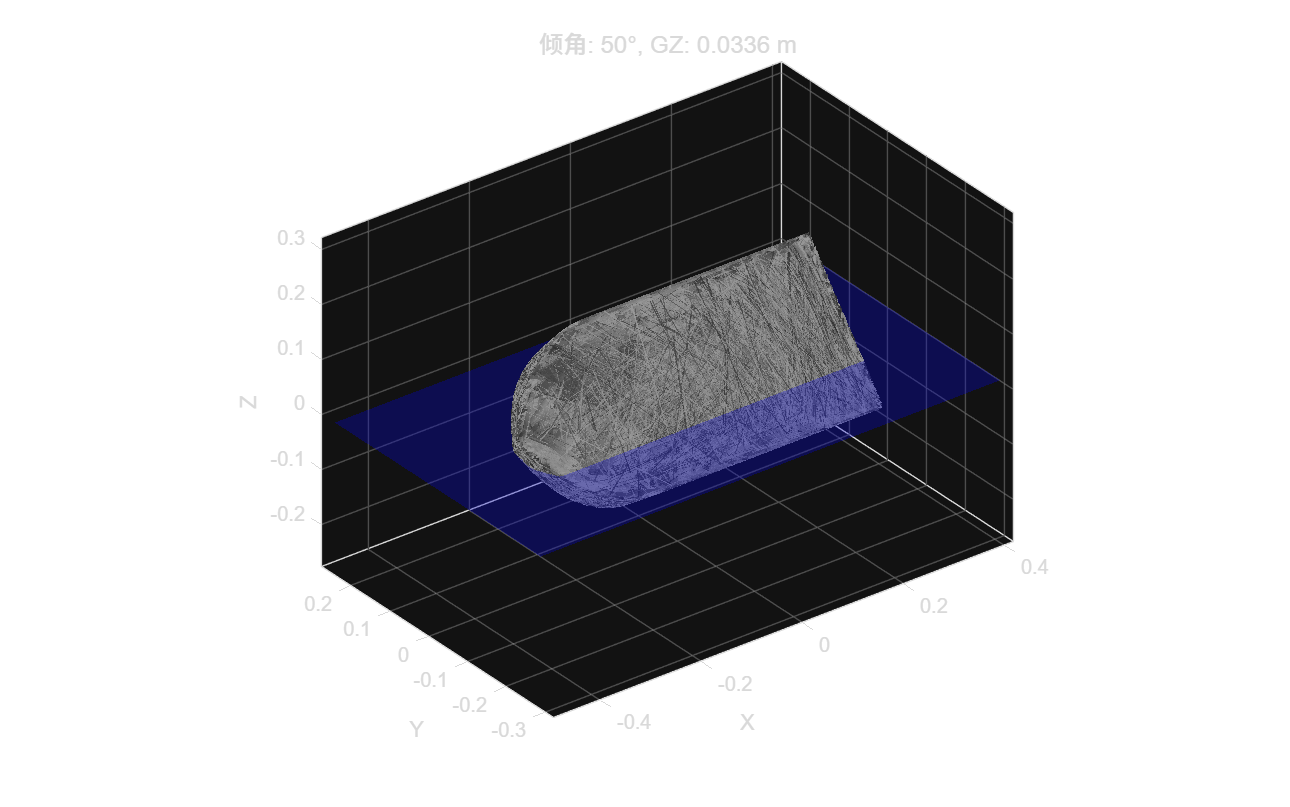

计算倾角: 55° ... 

GZ = 0.031 m


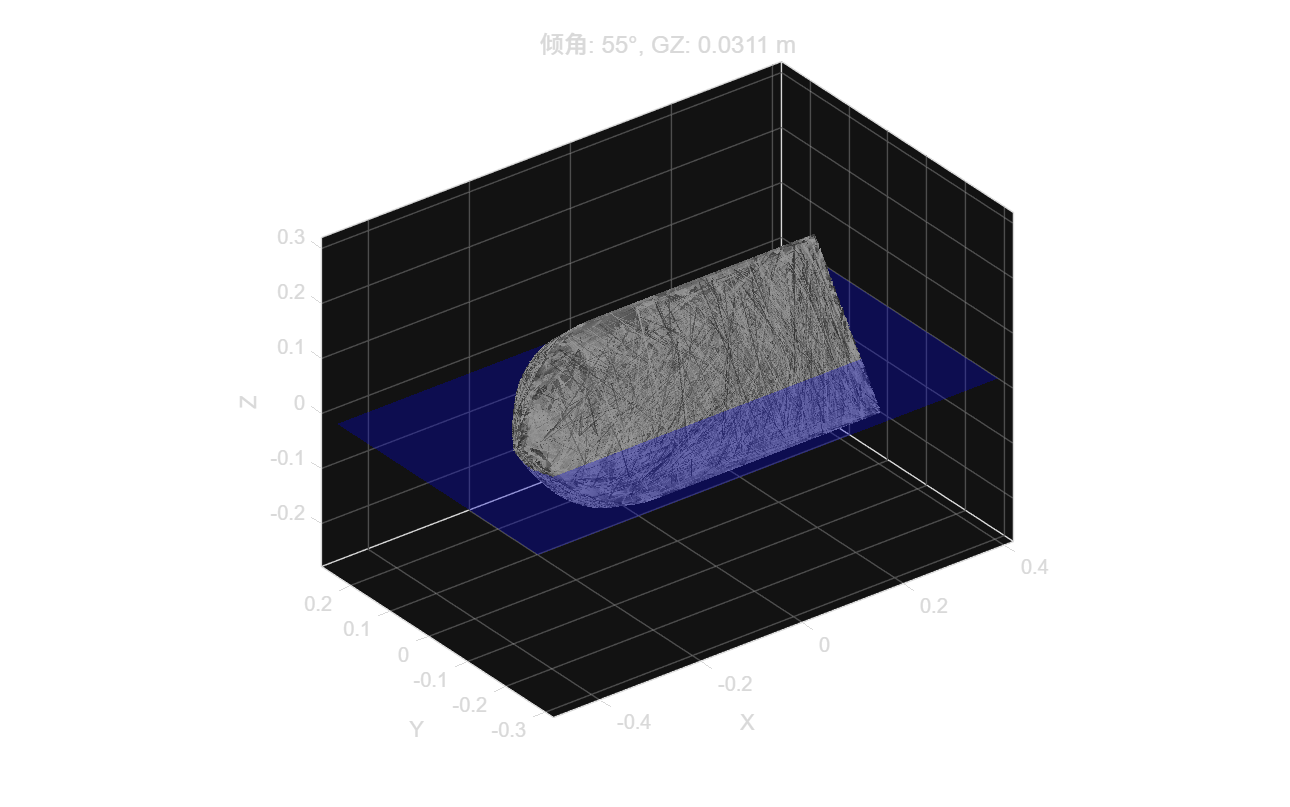

计算倾角: 60° ... 

GZ = 0.028 m


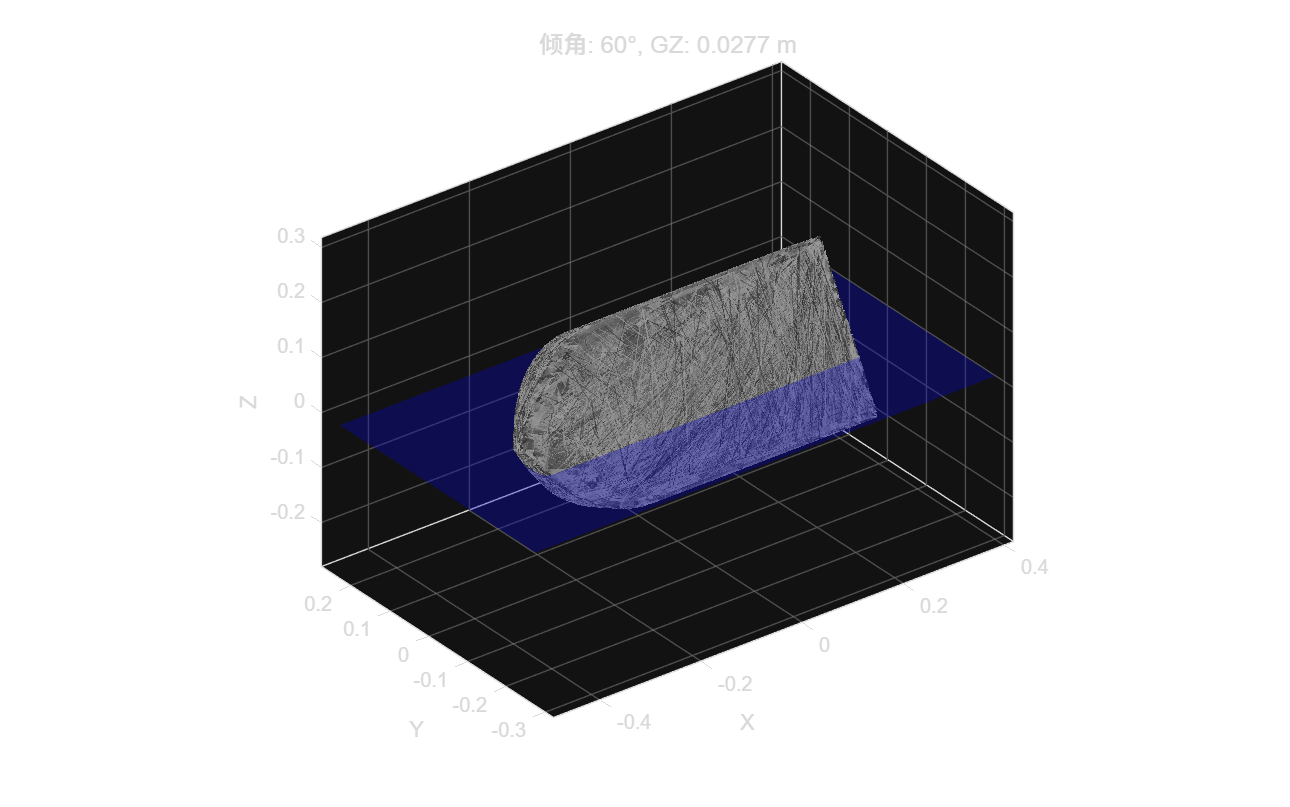

计算倾角: 65° ... 

GZ = 0.024 m


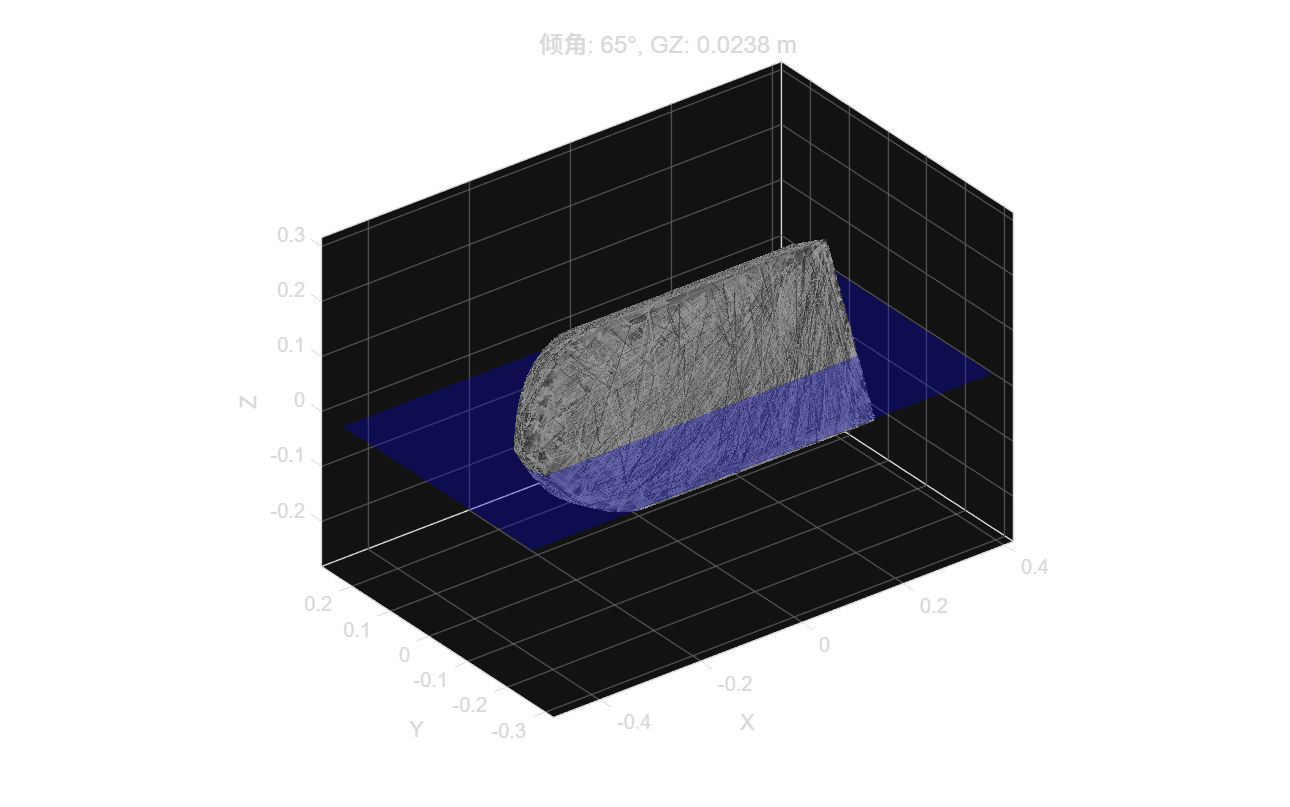

计算倾角: 70° ... 

GZ = 0.019 m


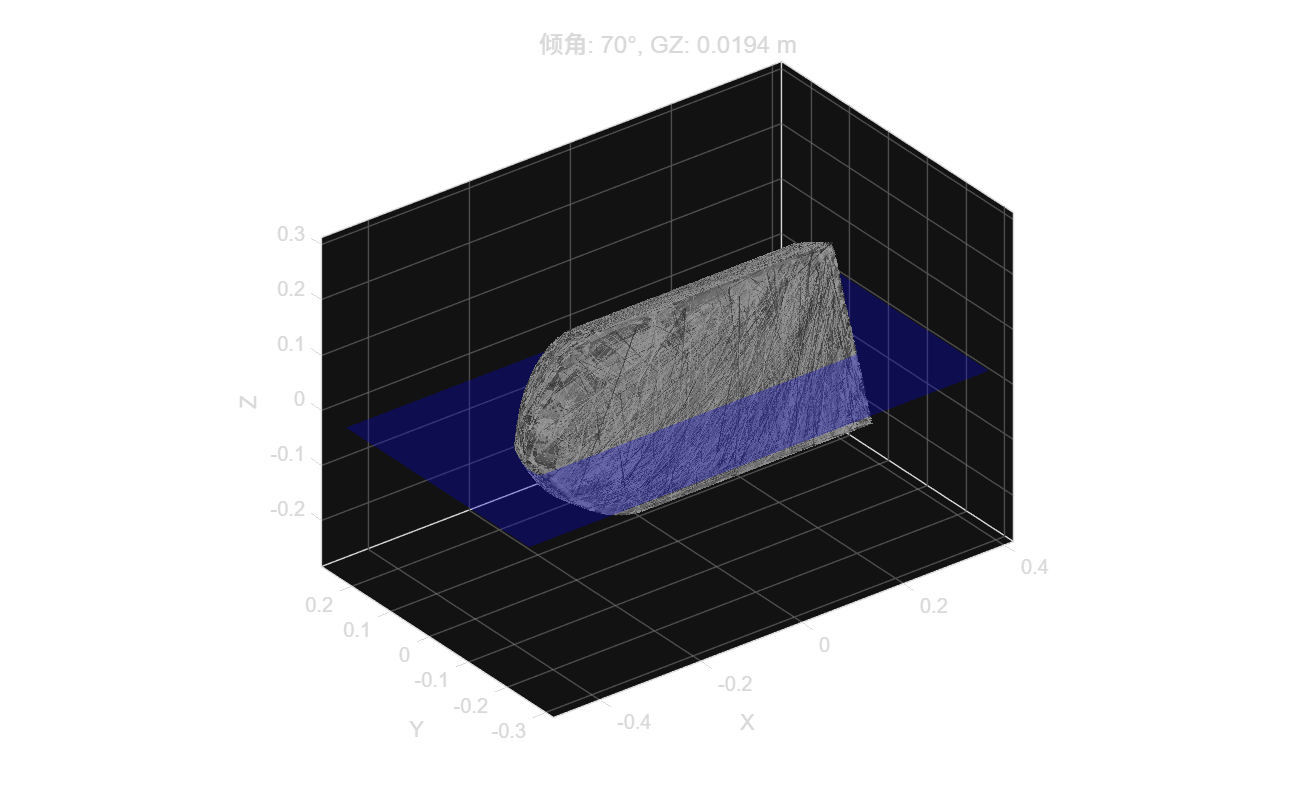

计算倾角: 75° ... 

GZ = 0.015 m


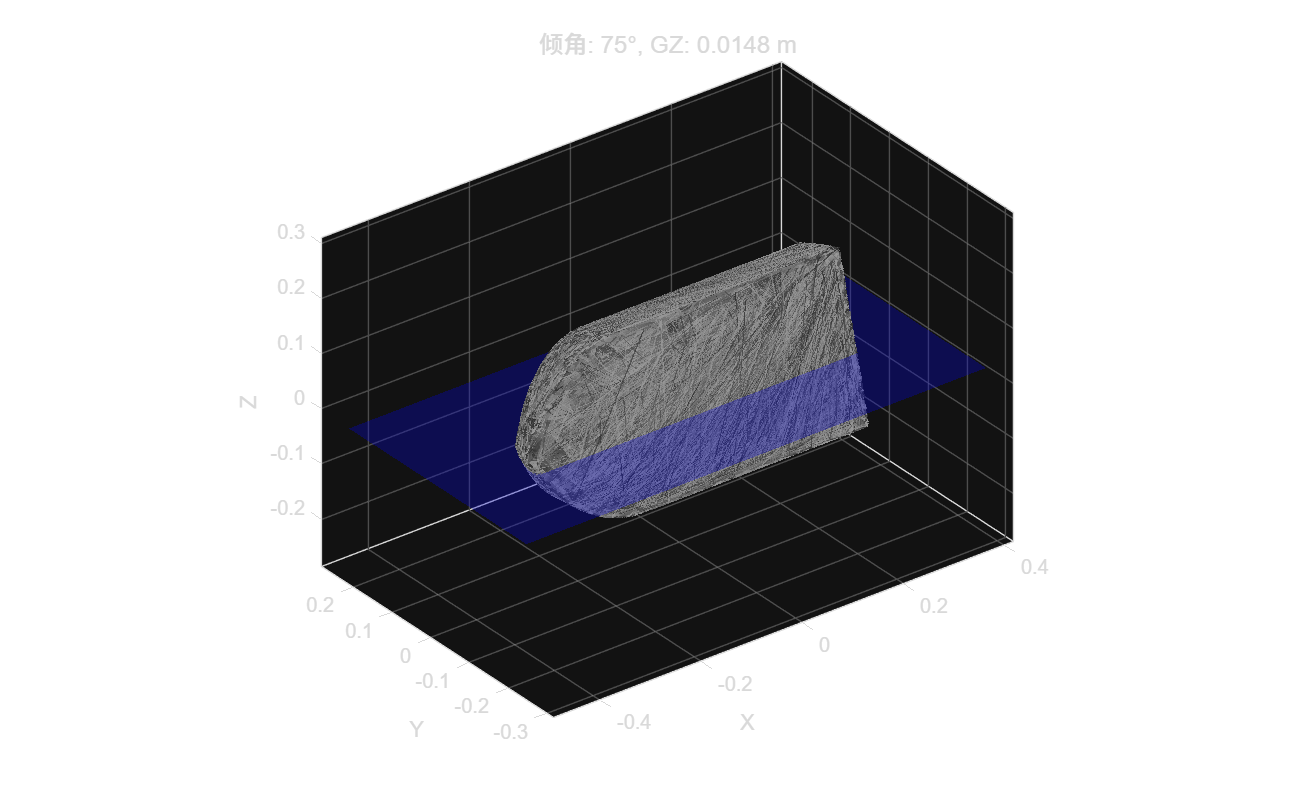

计算倾角: 80° ... 

GZ = 0.010 m


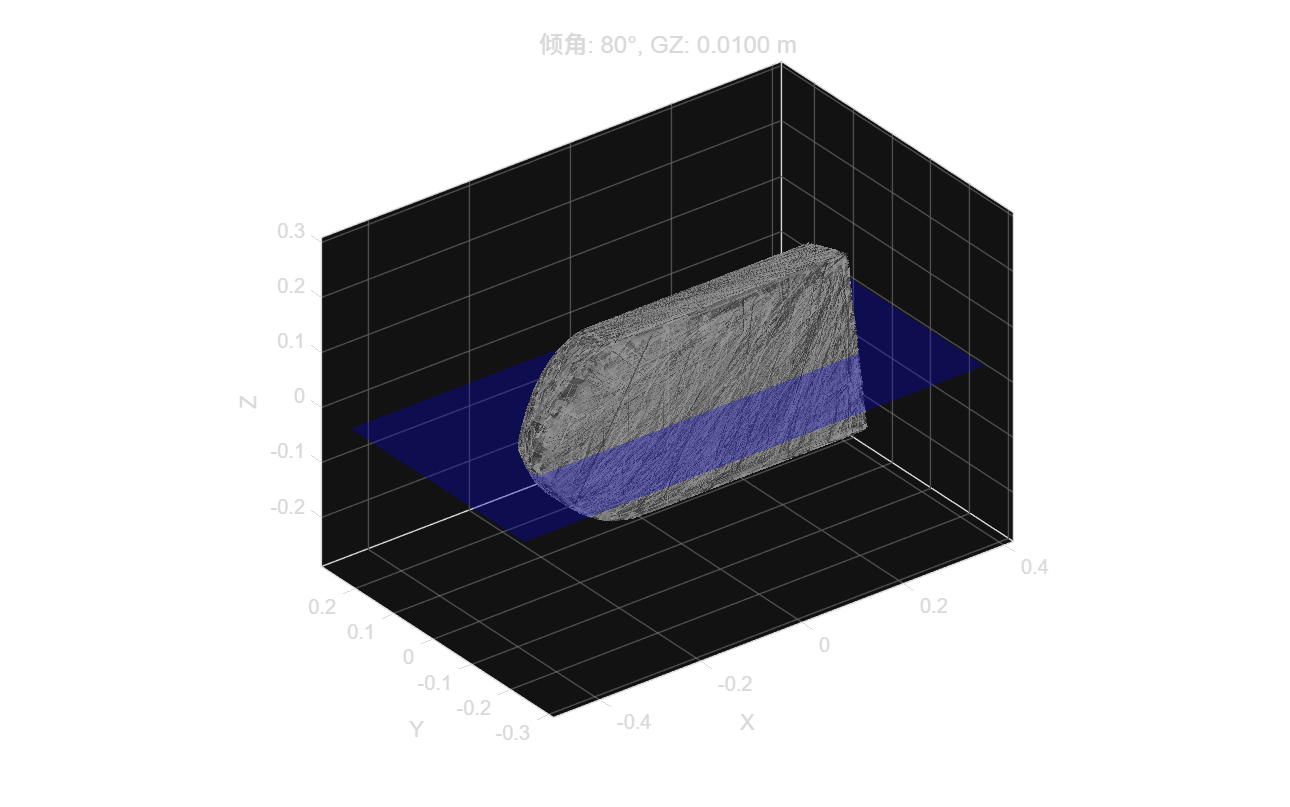

计算倾角: 85° ... 

GZ = 0.005 m


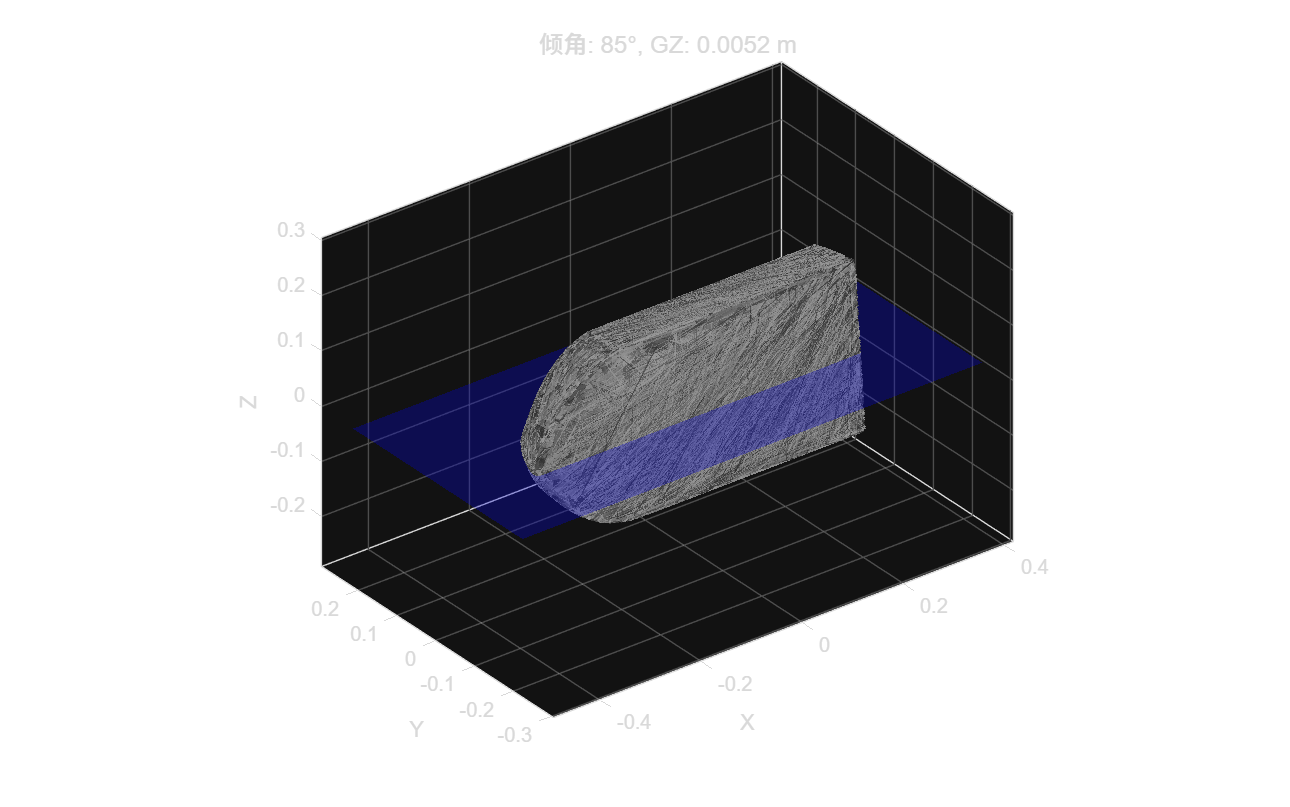

计算倾角: 90° ... 

GZ = 0.000 m


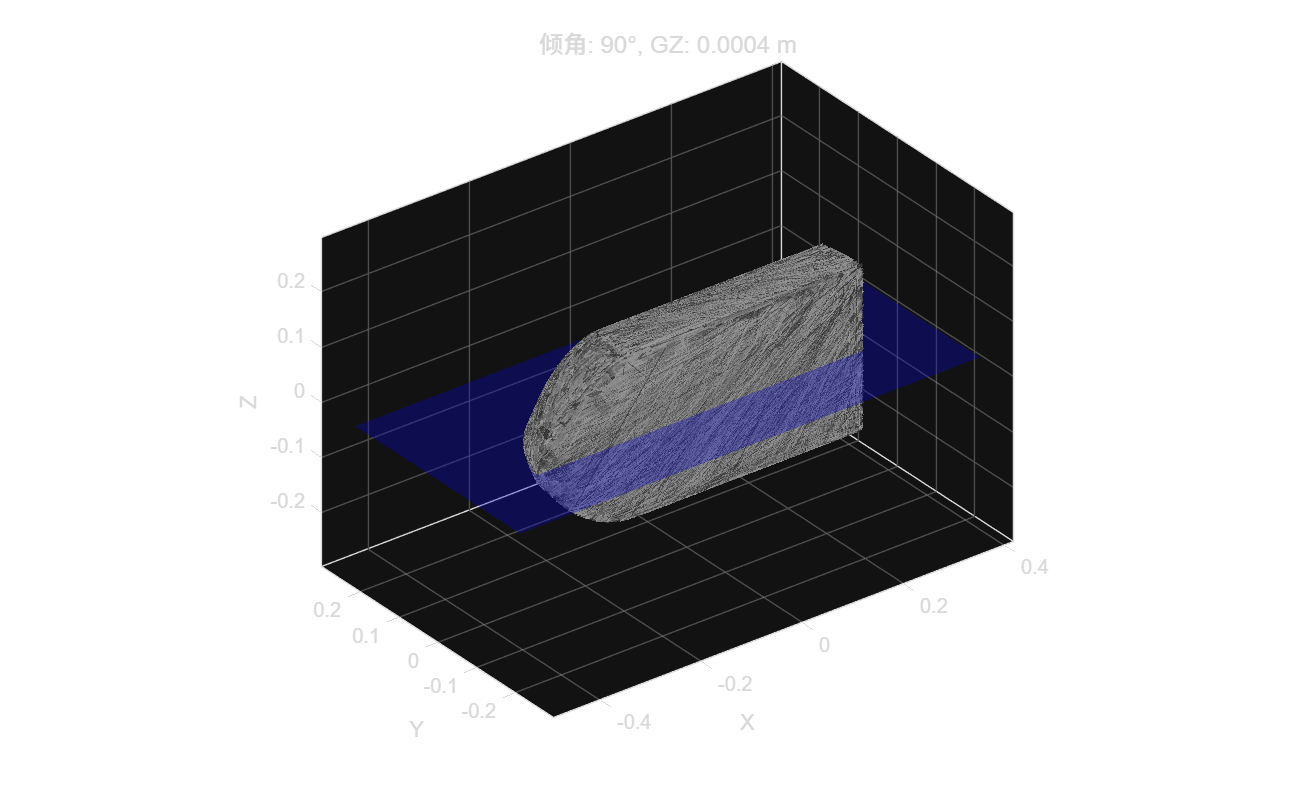


for i = 1:length(angles)
    deg = angles(i);
    fprintf('计算倾角: %d° ... ', deg);
    
    % A. 旋转船体 (绕原点，即船中)
    nodes_rot = rotate_nodes(nodes, deg);
    cg_rot = rotate_point(cg_local, deg);
    
    % B. 寻找平衡吃水 (Heave Balance)
    z_min_r = min(nodes_rot(3,:)); 
    z_max_r = max(nodes_rot(3,:));
    draft = find_draft(nodes_rot, elements, target_disp, z_min_r, z_max_r);
    
    % C. 计算浮心 (使用平滑积分，杜绝锯齿)
    [v_disp, cb] = calc_submerged_props_smooth(nodes_rot, elements, draft);
    
    % D. 计算 GZ
    % 在旋转后的坐标系中，GZ 即为 重心Y - 浮心Y (取反以符合正值代表复原力矩的习惯)
    % 之前的逻辑是 cb(2) - cg_rot(2)，导致稳定船只出现负值
    gz = cg_rot(2) - cb(2);
    
    results_angle(end+1) = deg;
    results_gz(end+1) = gz;
    
    fprintf('GZ = %.3f m\n', gz);
    
    % E. 绘图 (每个角度独立窗口)
    figure('Name', sprintf('倾角 %d°', deg), 'Color', 'w', 'Units', 'normalized', 'OuterPosition', [0 0 1 1]);
    hold on; axis equal; box on; grid on;
    title(sprintf('倾角: %d°, GZ: %.4f m', deg, gz), 'FontSize', 12);
    
    % 1. 画三维船体 (使用之前提取的 F_surface)
    % 使用 trisurf 绘制旋转后的表面，效果远好于 scatter
    p_ship = trisurf(F_surface, nodes_rot(1,:), nodes_rot(2,:), nodes_rot(3,:), ...
        'FaceColor', [0.6 0.6 0.6], 'EdgeColor', 'none', 'FaceAlpha', 0.6);
    
    % 2. 画水面 (半透明蓝色平面)
    % 动态计算水面大小，覆盖整个船体范围
    x_r = [min(nodes_rot(1,:)), max(nodes_rot(1,:))];
    y_r = [min(nodes_rot(2,:)), max(nodes_rot(2,:))];
    margin = max(range(x_r), range(y_r)) * 0.2;
    
    patch([x_r(1)-margin, x_r(2)+margin, x_r(2)+margin, x_r(1)-margin], ...
          [y_r(1)-margin, y_r(1)-margin, y_r(2)+margin, y_r(2)+margin], ...
          [draft draft draft draft], ...
          'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    
    % 3. 画重心与浮心 (三维球体)
    plot3(cg_rot(1), cg_rot(2), cg_rot(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    plot3(cb(1), cb(2), cb(3), 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
    
    % 4. 辅助线
    plot3([cg_rot(1), cb(1)], [cg_rot(2), cb(2)], [cg_rot(3), cb(3)], 'k-', 'LineWidth', 1.5);
    
    % 5. 设置视图
    xlabel('X'); ylabel('Y'); zlabel('Z');
    view(3); % 保持三维视角
    
    % 添加光照，否则三维物体看起来像平面的
    light('Position', [0 -10 10], 'Style', 'infinite');
    lighting gouraud;
    material dull;
end

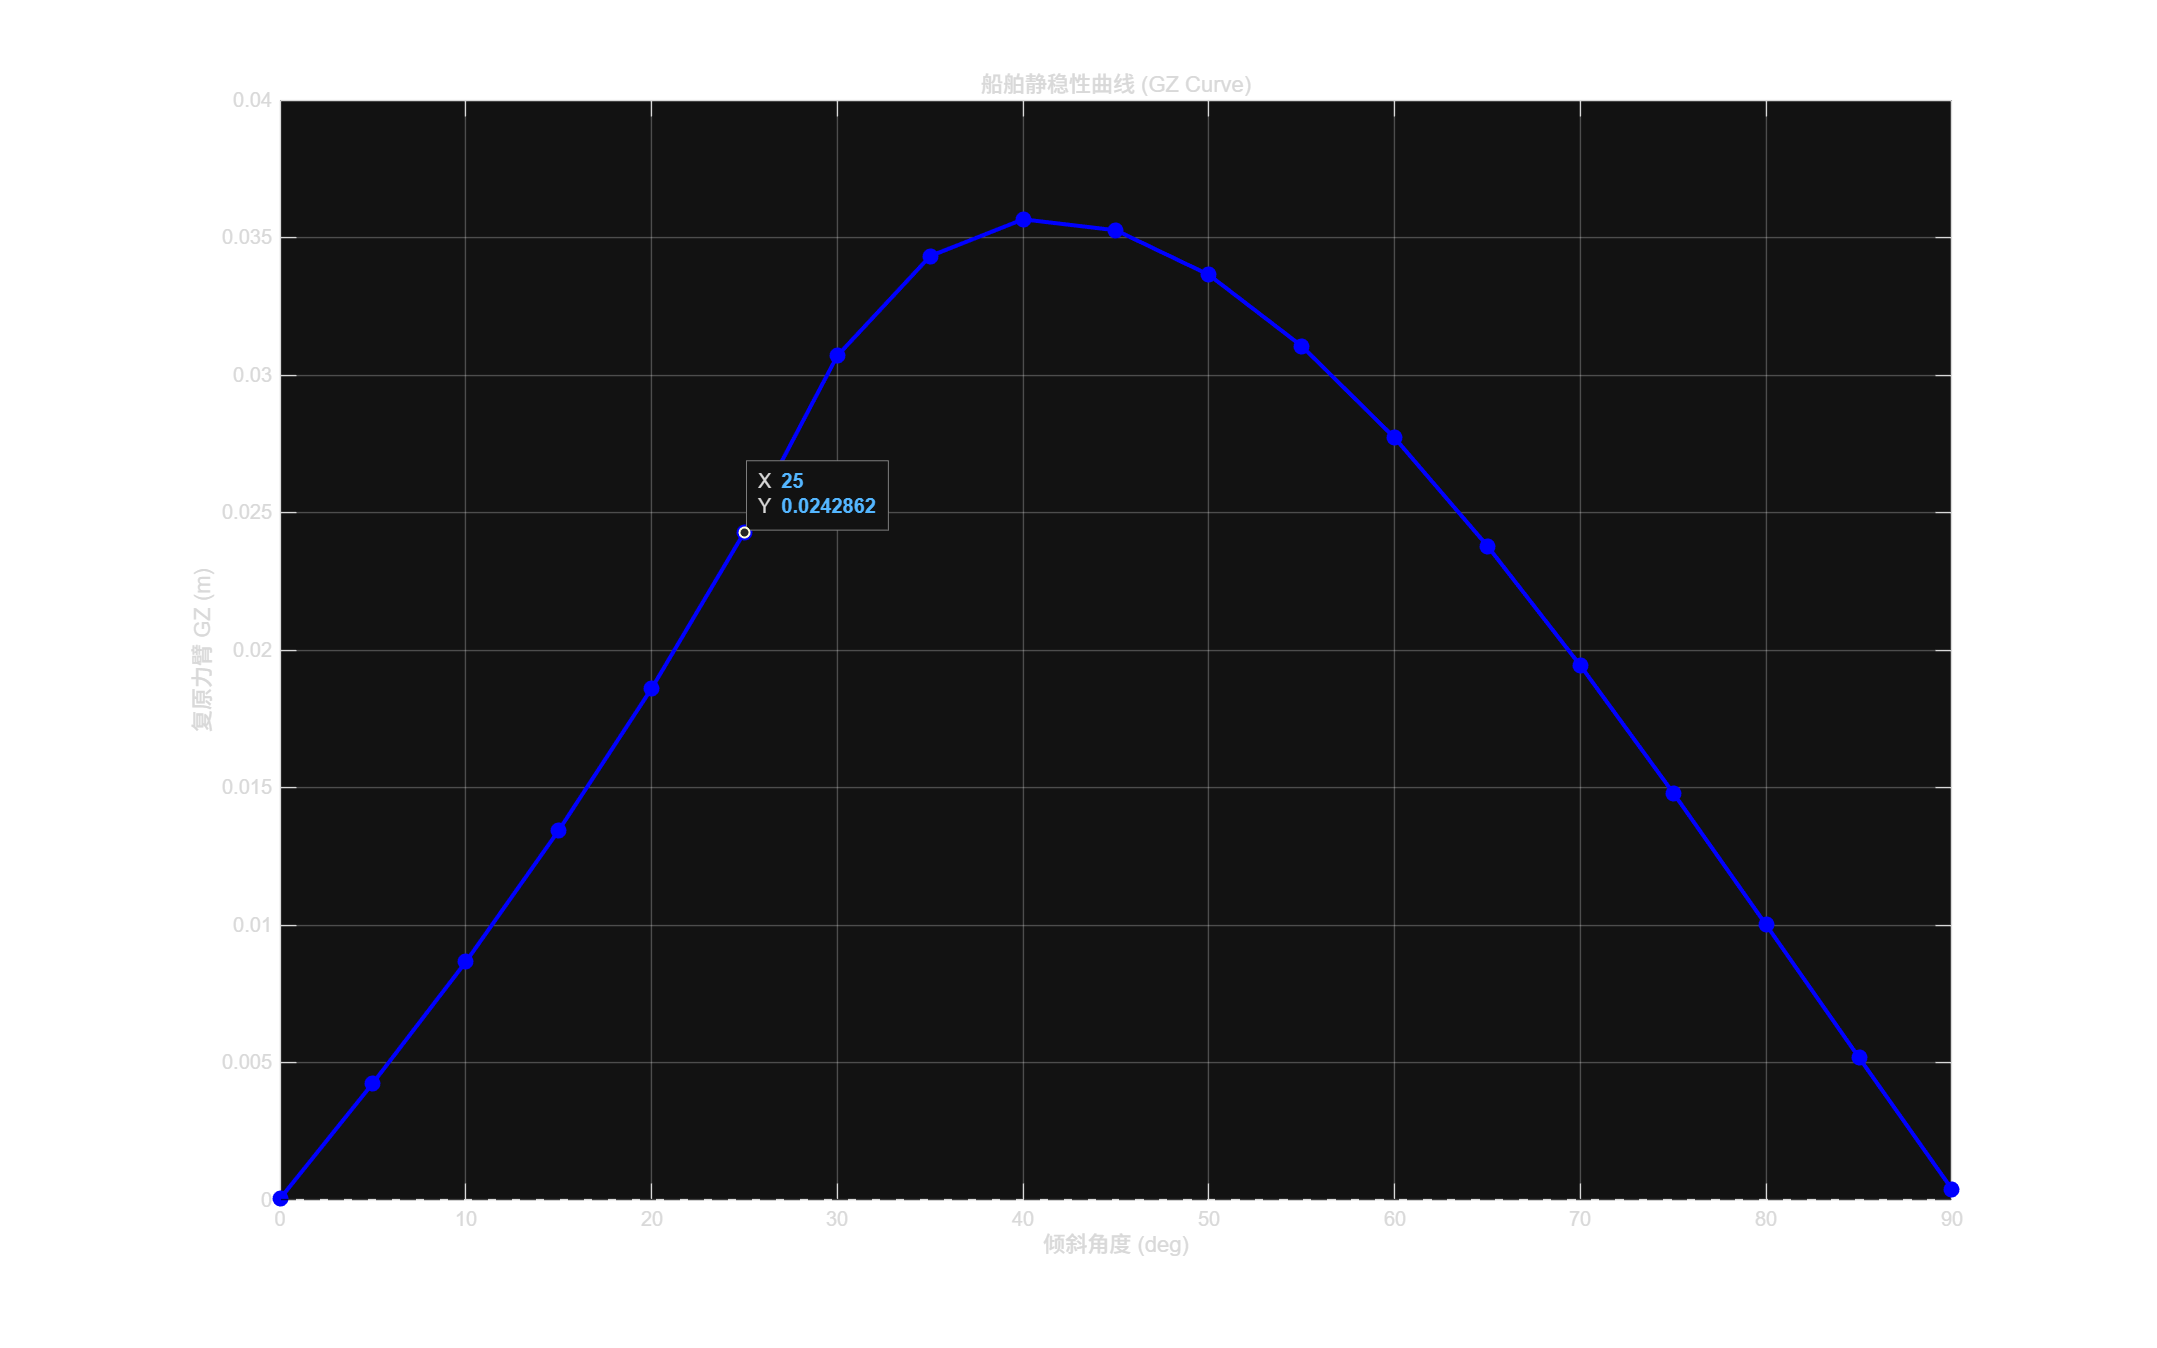


%% 6. 汇总 GZ 曲线图
figure('Name', '静稳性曲线', 'Color', 'w', 'Units', 'normalized', 'OuterPosition', [0 0 1 1]);
plot(results_angle, results_gz, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
grid on;
title('船舶静稳性曲线 (GZ Curve)');
xlabel('倾斜角度 (deg)'); ylabel('复原力臂 GZ (m)');
yline(0, 'k--');

if max(results_gz) < 0
    text(10, max(results_gz), '警告: 船舶不稳定 (GZ < 0)', 'Color', 'r', 'FontSize', 14);
end


% ================================================================
%                          核心算法函数
% ================================================================

% 1. 基础属性计算
function [vol, cg] = calc_mesh_props(nodes, elements)
    vol = 0; moment = [0;0;0];
    for i = 1:size(elements, 2)
        idx = elements(:,i);
        pts = nodes(:, idx);
        % 四面体体积
        v = abs(det([pts(:,2)-pts(:,1), pts(:,3)-pts(:,1), pts(:,4)-pts(:,1)])) / 6;
        c = mean(pts, 2);
        vol = vol + v;
        moment = moment + v * c;
    end
    cg = (moment / vol)';
end

% 2. [关键修正] 平滑积分计算水下属性
% 解决了原先 "if num_below > 0" 导致的锯齿问题
function [vol_sub, cb] = calc_submerged_props_smooth(nodes, elements, z_water)
    vol_sub = 0; moment = [0;0;0];
    
    for i = 1:size(elements, 2)
        idx = elements(:,i);
        pts = nodes(:, idx);
        zs = pts(3, :);
        
        z_min = min(zs);
        z_max = max(zs);
        
        % 计算该单元在水下的体积比例 (线性近似)
        if z_max <= z_water
            ratio = 1.0; % 完全淹没
        elseif z_min >= z_water
            ratio = 0.0; % 完全离开水面
        else
            % 被截断：线性插值比例
            % 这种方法虽然比严格几何切割稍微不准，但对于致密网格极其平滑
            % 能够彻底消除锯齿震荡
            if z_max > z_min
                ratio = (z_water - z_min) / (z_max - z_min);
            else
                ratio = 0; % 避免除以零
            end
            % 对体积进行立方修正可以更准，但简单的线性比例足以消除锯齿且保持趋势正确
            ratio = max(0, min(1, ratio)); 
        end
        
        if ratio > 0
            v_full = abs(det([pts(:,2)-pts(:,1), pts(:,3)-pts(:,1), pts(:,4)-pts(:,1)])) / 6;
            c_full = mean(pts, 2);
            
            v_eff = v_full * ratio;
            
            % 简单的重心修正：假设部分淹��的单元重心仍在几何中心附近
            % 对于极小网格，此误差可忽略
            vol_sub = vol_sub + v_eff;
            moment = moment + v_eff * c_full;
        end
    end
    
    if vol_sub == 0
        cb = [0,0,0];
    else
        cb = (moment / vol_sub)';
    end
end

% 3. 寻找平衡吃水
function draft = find_draft(nodes, elements, target_disp, z_min, z_max)
    % 为了适配 fzero，我们需要封装一下只返回体积
    func_vol = @(z) get_vol_only(nodes, elements, z) - target_disp;
    
    try
        draft = fzero(func_vol, [z_min, z_max]);
    catch
        % 如果 fzero 失败（通常因为范围不对），用二分法兜底
        draft = (z_min + z_max)/2; 
        warning('fzero failed to find draft, using average.');
    end
end

function v = get_vol_only(nodes, elements, z)
    [v, ~] = calc_submerged_props_smooth(nodes, elements, z);
end

% 4. 旋转工具
function nodes_new = rotate_nodes(nodes, deg)
    theta = deg2rad(deg);
    c = cos(theta); s = sin(theta);
    R = [1,0,0; 0,c,-s; 0,s,c];
    nodes_new = R * nodes;
end

function p_new = rotate_point(p, deg)
    theta = deg2rad(deg);
    c = cos(theta); s = sin(theta);
    R = [1,0,0; 0,c,-s; 0,s,c];
    p_new = (R * p')';
end